Pomiar czasu dla Matlaba

tic;
img_rgb = imread('input.tif');
img_rgb = im2double(img_rgb);

img_hsv = rgb2hsv(img_rgb);

H = img_hsv(:,:,1);  % Hue: 0–1
S = img_hsv(:,:,2);  % Saturation: 0–1

%Skalowanie Hue do 0–179 i Saturation do 0–255
H = floor(H * 179); 
S = floor(S * 255);

hist2d = zeros(180, 256);

[rows, cols] = size(H);
for i = 1:rows
    for j = 1:cols
        hue = H(i,j) + 1;
        sat = S(i,j) + 1;
        hist2d(hue, sat) = hist2d(hue, sat) + 1;
    end
end

elapsedTime = toc;
disp(['Czas wykonania: ', num2str(elapsedTime), ' sekund']);

Czas wykonania: 1.6764 sekund


Zapis do obrazu RGB

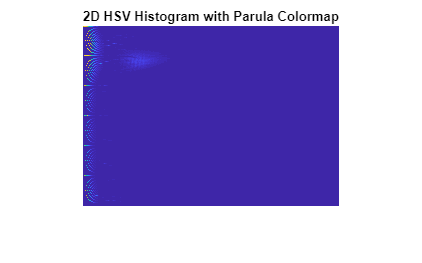

hist2d_norm = hist2d / max(max(hist2d));
parula_map = parula(64);
idx_map = round(hist2d_norm * 63) + 1;

[h, w] = size(hist2d_norm);
hist_matlab = zeros(h, w, 3);

for ch = 1:3
    channel = reshape(parula_map(idx_map(:), ch), h, w);
    hist_matlab(:,:,ch) = channel;
end

imshow(hist_matlab);
title('2D HSV Histogram with Parula Colormap');

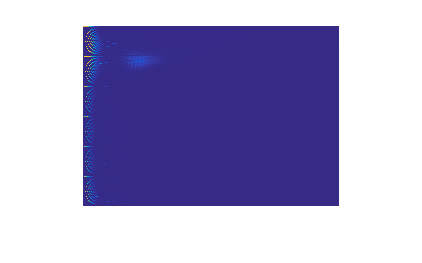

hist2d_openCL = imread("outputHist2D_openCL.bmp");
imshow(hist2d_openCL)

Różnica między obrazami RGB

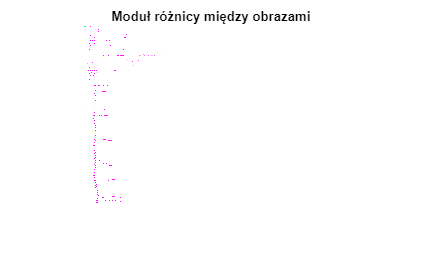

img1 = hist2d_openCL;
img2 = hist_matlab;

img1 = im2double(img1);
img2 = im2double(img2);

% Obliczenie modułu różnicy
diff_abs = abs(img1 - img2) * 255;

% Wyświetlenie różnicy
imshow(diff_abs);
title('Moduł różnicy między obrazami');

Porównanie wartości histogramów

hist2d

hist2d =       116189      128911      124748      117364      104290       88109       71034       58730       63104       34893       16057        9285        5564       10796       10481        2946         530         283         176         171         174         153         171         108          91         148          81         124          80          50          98          71          70          69          38          51          65          79          53          74          80          39          54          51          54          57          49          53          50          39
           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        1022         583         231         104          50          21          15          15           7           9          12          12          25          21          26          38          58      

histogram_values_CL = readmatrix("histogram_output.csv")

histogram_values_CL =       116189      128911      124748      117365      104343       88060       71043       58729       63091       34902       16048        9321        5563       10778       11514        1905         537         267         176         174         171         153         171         108          91         148          81         124          80          55          93          71          70          69          38          51          65          79          53          74          80          39          54          51          55          56          49          53          50          38
           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0          23         492         208          98          53          17           8           5           2           5           8           6          10          10          11          17     

diff = abs(histogram_values_CL - hist2d)

diff =            0           0           0           1          53          49           9           1          13           9           9          36           1          18        1033        1041           7          16           0           3           3           0           0           0           0           0           0           0           0           5           5           0           0           0           0           0           0           0           0           0           0           0           0           0           1           1           0           0           0           1
           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0         999          91          23           6           3           4           7          10           5           4           4           6          15          11          15          21          23        

Histogramy 1D

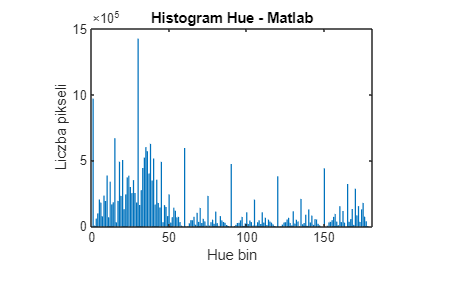

hist1D = sum(hist2d, 2);
bar(hist1D);
xlabel('Hue bin');
ylabel('Liczba pikseli');
title('Histogram Hue - Matlab');

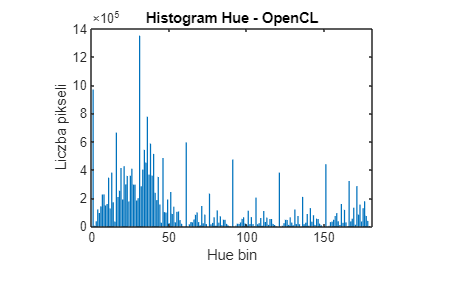

hist1D = sum(histogram_values_CL, 2);
bar(hist1D);
xlabel('Hue bin');
ylabel('Liczba pikseli');
title('Histogram Hue - OpenCL');

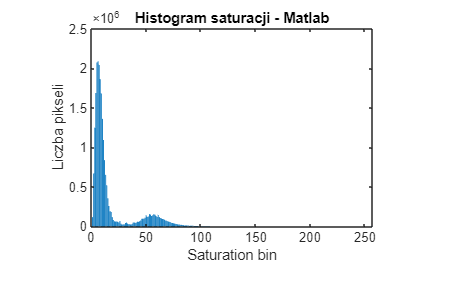

hist1D = sum(hist2d, 1);
bar(hist1D);
xlabel('Saturation bin');
ylabel('Liczba pikseli');
title('Histogram saturacji - Matlab');

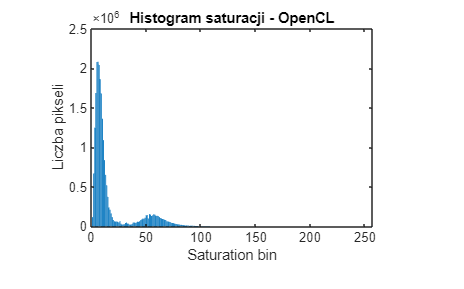

hist1D = sum(histogram_values_CL, 1);
bar(hist1D);
xlabel('Saturation bin');
ylabel('Liczba pikseli');
title('Histogram saturacji - OpenCL');